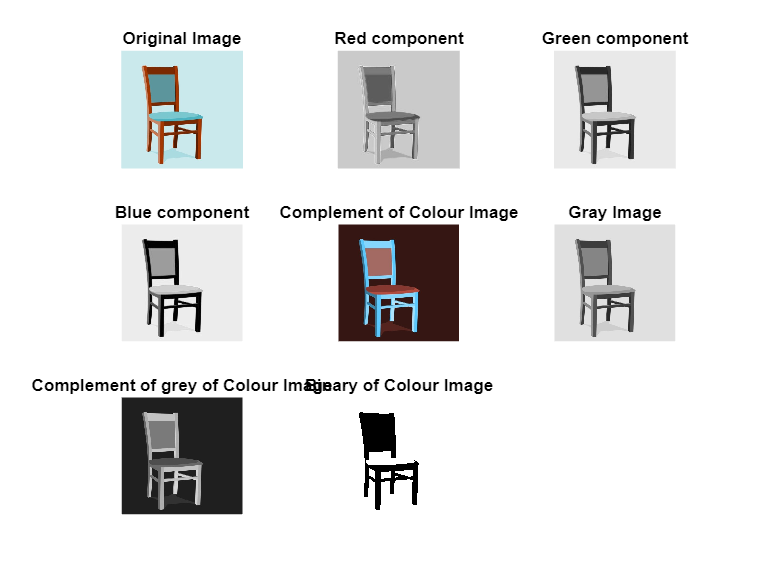

% Simulation and display of an image, negative of an image
% binary and grey scale conversion of image

clc
i=imread("original image.jpg");

% Original Image
subplot(3,3,1)
imshow(i);
title('Original Image')

% Red component
r=i(:,:,1);
subplot(3,3,2)
imshow(r);
title('Red component');

% Green component
g=i(:,:,2);
subplot(3,3,3);
imshow(g);
title('Green component')

% Blue component
b=i(:,:,3);
subplot(3,3,4);
imshow(b);
title('Blue component')

% Display complement of colour image
comp=imcomplement(i);
subplot(3,3,5);
imshow(comp);
title('Complement of Colour Image');

% Color to Gray image
greyi=rgb2gray(i);
subplot(3,3,6);
imshow(greyi);
title('Gray Image')

% Display complement of grey of image
comp_grey=imcomplement(greyi);
subplot(3,3,7);
imshow(comp_grey);
title('Complement of grey of Colour Image');

% Binary of colour image
subplot(3,3,8);
th = graythresh(greyi); %First finding threshold for the binarization
bin=imbinarize(greyi,th);
imshow(bin);
title('Binary of Colour Image');

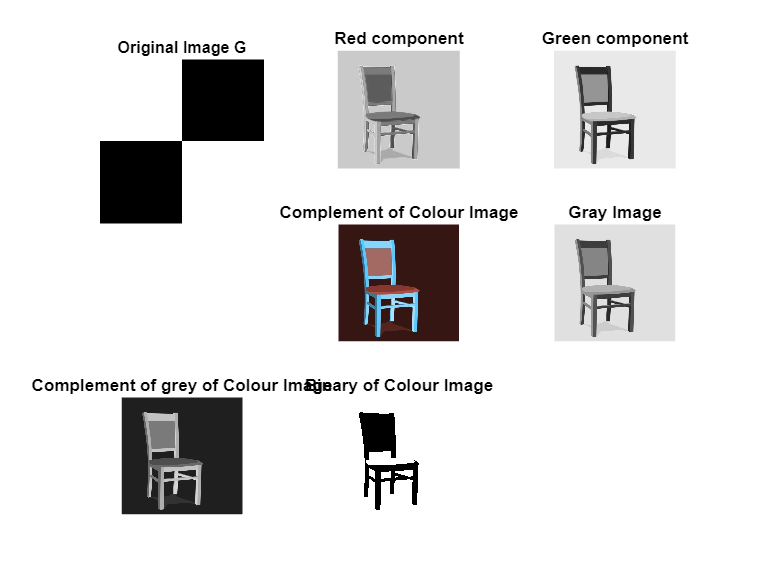




% Simulation of an image(Arithmetic and logic Operations)
a=ones(40);
b=zeros(40);
g=[[a b];[b a]];
h=[[b b];[a a]];
A=g+h;
B=g-h;
C=g*h;
D=g/4;
subplot(2,3,1);
imshow(g);
title('Original Image G');

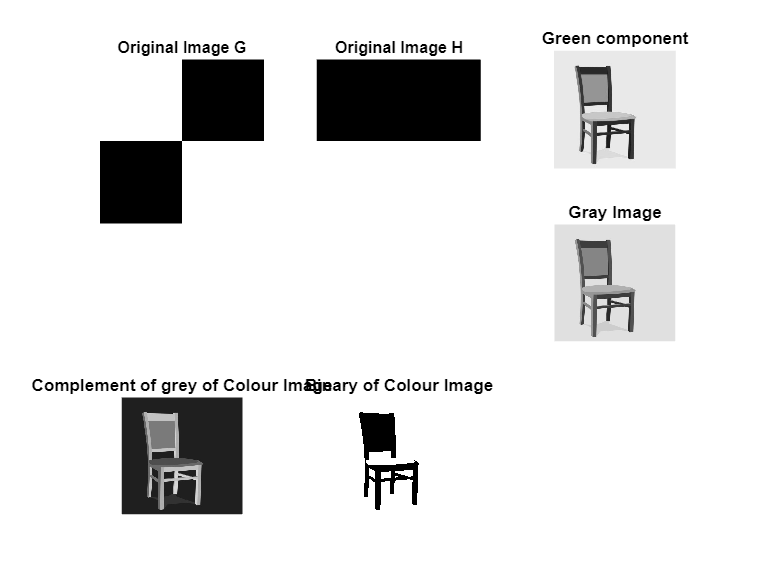


subplot(2,3,2);
imshow(h);
title('Original Image H');

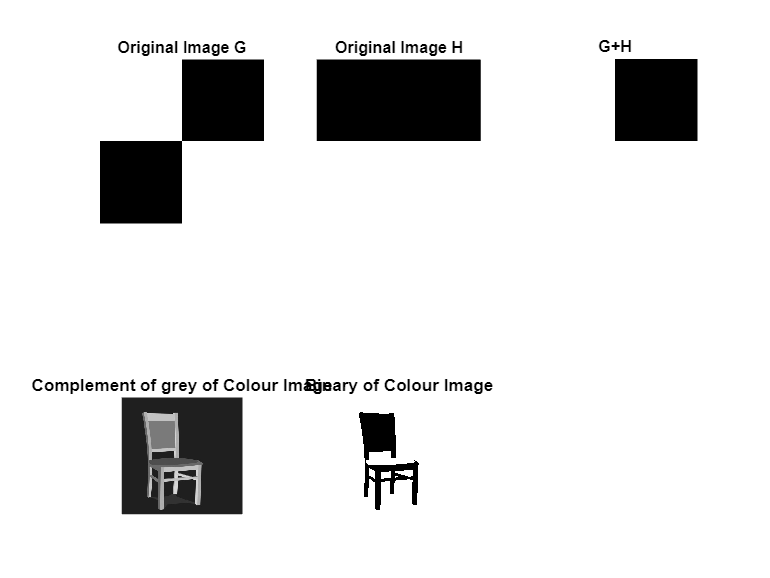


subplot(2,3,3);
imshow(A);
title('G+H');

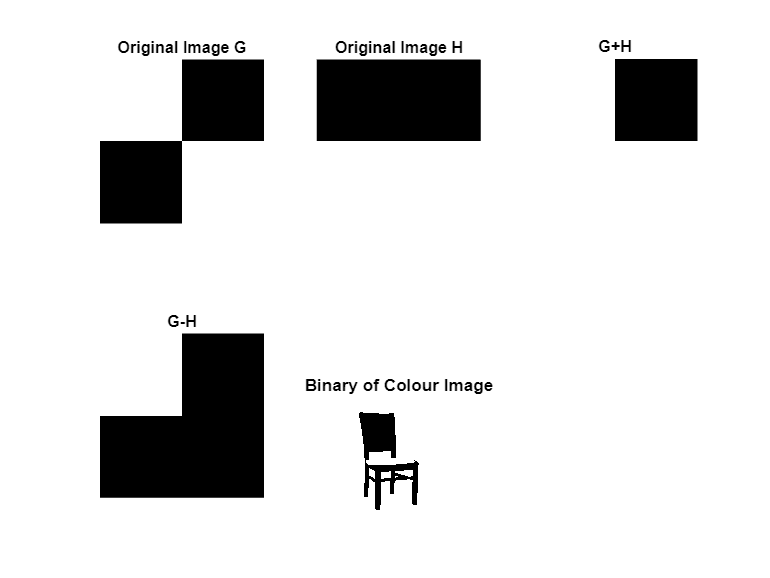


subplot(2,3,4);
imshow(B);
title('G-H');

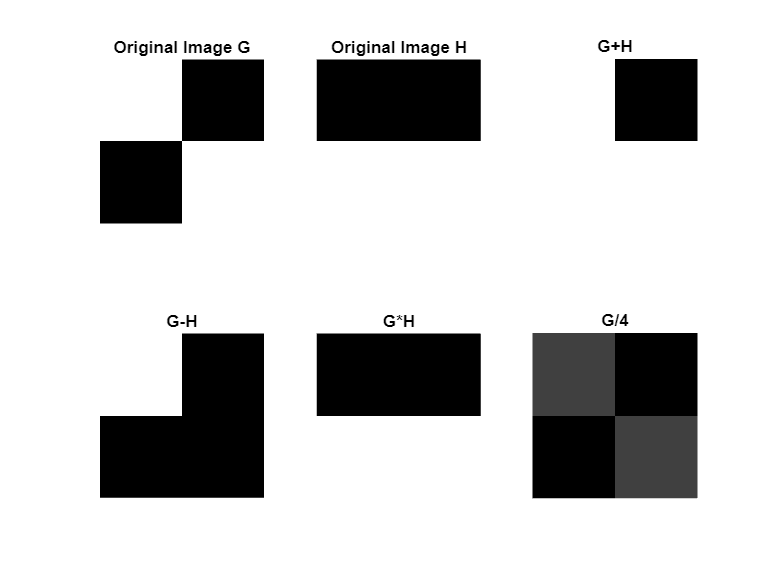


subplot(2,3,5);
imshow(C);
title('G*H');

subplot(2,3,6);
imshow(D);
title('G/4');